# Initializer.mlx

## This file specifies the simulation parameters, stores the outputs from the PSSE simulation and plots them.

#### This script changes all interpretation parameters to LaTeX.

latex_interpreter

#### Specify simulation parameters: system name, sampling rate, window size, etc. and fish out desired output parameters from the PSSE outfile.

tic
system_name = 'ieee9'

system_name = 'ieee9'

run_number = 7

run_number = 7

downsampling_ratio = 1;
sampling_rate = 0.3/30;
T = 15%Window size in seconds

T = 15

W = T/sampling_rate

W = 1500

window_moving_ratio = 0.05;
bifurcation_limit  = 0.90

bifurcation_limit = 0.9000

convolutionMarginRatio = 0.00;

simulation_outputs_folder = "C:\Users\aryan\Documents\" + ...
    "documents_general\python_files\eld895_simulation_psse\" + ...
    "simulation_outputs\";

analysis_outputs_folder = 'saved_outputs/'; %subfolder where data will be stored

xlsxname = strcat(simulation_outputs_folder, system_name, '_outfile_', ...
    num2str(run_number), '.xlsx')

xlsxname = "C:\Users\aryan\Documents\documents_general\python_files\eld895_simulation_psse\simulation_outputs\ieee9_outfile_7.xlsx"

opts = detectImportOptions(xlsxname, 'NumHeaderLines', 3);
opts.VariableNamingRule = 'modify';
warning off; %only for one readtable warning
xlsxtable = readtable(xlsxname, opts);
warning on;

string0 = 'Time';
string1 = 'POWR';
string2 = 'BUS';
string3 = 'PLOD';
string4 = 'FREQ';
string5 = 'VOLT';
string6 = 'CKT';
string7 = 'MVA';

varNames = xlsxtable.Properties.VariableNames;
times = xlsxtable(:, contains(varNames,string0));
times.Properties.VariableNames = {'time'};
rows = times.time > 1.0;
times = times.time(times.time > 1.0);


pgens = xlsxtable(rows, contains(varNames, string1) ...
    & contains(varNames, string2));
pgensArr = table2array(pgens);
save(strcat(analysis_outputs_folder,'pgens_',system_name,'.mat'), 'pgensArr');

ploads = xlsxtable(rows, contains(varNames, string3));
ploadsArr = table2array(ploads);
save(strcat(analysis_outputs_folder,'ploads_',system_name,'.mat'), 'ploadsArr');

freqs = xlsxtable(rows,contains(varNames,string4));
freqsArr = table2array(freqs);
save(strcat(analysis_outputs_folder,'freqs_',system_name,'.mat'), 'freqsArr');

volts = xlsxtable(rows, contains(varNames, string5));
voltsRawArr = table2array(volts);
save(strcat(analysis_outputs_folder,'voltsRaw_',system_name,'.mat'), 'voltsRawArr');

numIterations = size(volts, 1)

numIterations = 11598

numBuses = size(volts, 2)

numBuses = 9


busesToPlot = numBuses

busesToPlot = 9

N = busesToPlot;
fun = @(m)sRGB_to_OSAUCS(m, true, true); % recommended OSA-UCS
addpath("C:\Users\aryan\Documents\documents_general" + ...
    "\dablab_files\eld895_analysis\maxdistcolor")
rgb = maxdistcolor(N, fun);

volts = volts{:, :};
[voltageSamplingStartsFrom, startIdx] = max(volts);
bifurcationIdx = find(volts < bifurcation_limit,...
    1, 'first')

bifurcationIdx = 8136

lastIdx = size(volts, 1)

lastIdx = 11598

voltsTruncatedArr = volts(1:bifurcationIdx, :);
save(strcat(analysis_outputs_folder, 'voltsTruncated_', ...
    system_name, '_', num2str(run_number), '.mat'), 'voltsTruncatedArr');


variableList = {'system_name', 'run_number', ...
    'sampling_rate', 'downsampling_ratio', 'T','W', ...
    'window_moving_ratio', 'bifurcation_limit', ...
    'bifurcationIdx', 'lastIdx', 'convolutionMarginRatio'};
firstRow = {system_name, run_number, ...
    sampling_rate, downsampling_ratio, T, W, ...
    window_moving_ratio, bifurcation_limit, ...
    bifurcationIdx, lastIdx, convolutionMarginRatio};
nominalValuesTable = array2table(firstRow, 'VariableNames', variableList);
tableName = strcat(analysis_outputs_folder, 'nominalValuesTable_', ...
    system_name, '_', num2str(run_number), '.csv')

tableName = 'saved_outputs/nominalValuesTable_ieee9_7.csv'

writetable(nominalValuesTable, tableName);

mvaflows = xlsxtable(rows, contains(varNames, string6) ...
    & contains(varNames, string7));
mvaflowNames = mvaflows.Properties.VariableNames;
indicesToDelete = [];
for i = 1:length(mvaflowNames)
    if mvaflowNames{i}(4) > mvaflowNames{i}(7)
        indicesToDelete = [indicesToDelete i];
    end
end
mvaflowNames(indicesToDelete) = [];
mvaflowsArr = mvaflows{:, mvaflowNames};
save(strcat(analysis_outputs_folder,'mvaflows_', system_name, ...
    '_', num2str(run_number), '.mat'), 'mvaflowsArr');

busesInEachBranch = [1 2 3 4 4 5 6 7 8];
currentsArr = ...
    1/sqrt(3)*...
    mvaflowsArr(:, busesInEachBranch)./volts(:, busesInEachBranch);
save(strcat(analysis_outputs_folder,'currents_', ...
    system_name, '_', num2str(run_number), '.mat'), 'currentsArr');


#### Import all the stored legend labels

store_legends

#### Start Plotting stuff

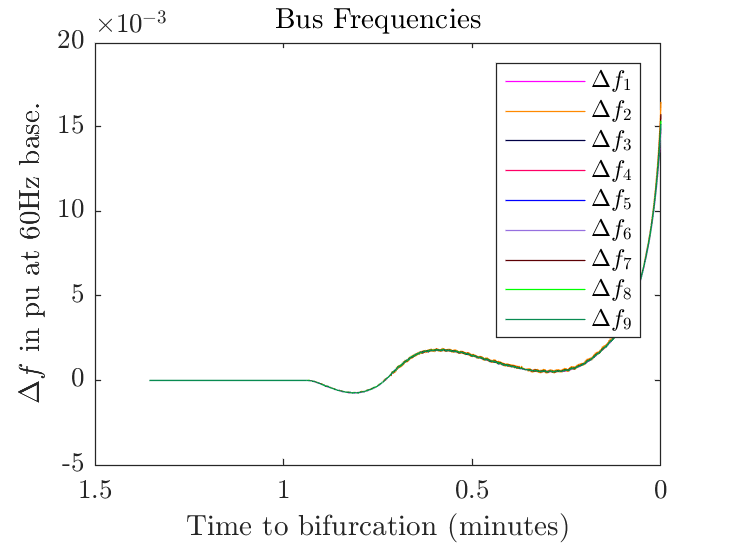

indicesToPlot1 = 1:bifurcationIdx;
xaxis1 = (bifurcationIdx - indicesToPlot1)*sampling_rate/(60);

figure('Name', 'Bus Frequencies vs Load Increment in Real Time')
plot(xaxis1, freqs{indicesToPlot1,1:end});
set(gca,'xdir','reverse')
set(gca,'colororder', rgb)
xlabel('Time to bifurcation (minutes)');
ylabel('$\Delta f$ in pu at 60Hz base.');
title('Bus Frequencies');
legend('$\Delta f_1$', '$\Delta f_2$', '$\Delta f_3$', ...
    '$\Delta f_4$', '$\Delta f_5$', '$\Delta f_6$', ...
    '$\Delta f_7$', '$\Delta f_8$', '$\Delta f_9$');

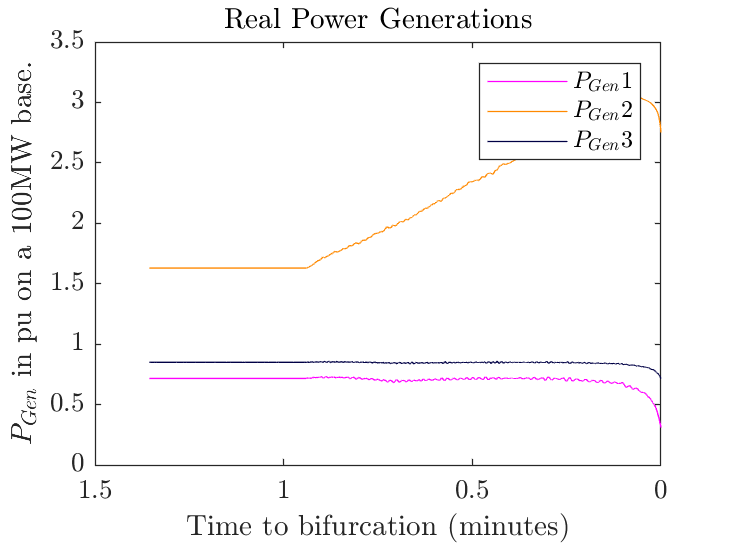


figure('Name', 'Real Power Generations vs Load Increment Real Time')
plot(xaxis1, pgens{indicesToPlot1,1:end});
set(gca,'xdir','reverse')
set(gca,'colororder', rgb)
xlabel('Time to bifurcation (minutes)');
ylabel('$P_{Gen}$ in pu on a 100MW base.');
title('Real Power Generations');
legend('$P_{Gen} 1$', '$P_{Gen} 2$', '$P_{Gen} 3$');

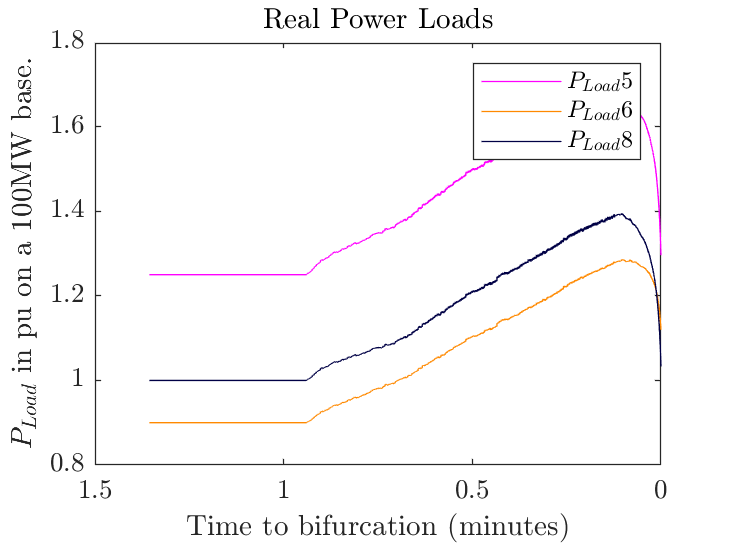


figure('Name', "Load Increments in Real Time")
plot(xaxis1, ploads{indicesToPlot1,1:end});
set(gca,'xdir','reverse')
set(gca,'colororder', rgb)
xlabel('Time to bifurcation (minutes)');
ylabel('$P_{Load}$ in pu on a 100MW base.');
title('Real Power Loads')
legend('$P_{Load} 5$', '$P_{Load} 6$', '$P_{Load} 8$');

#### Plot Bus Voltages

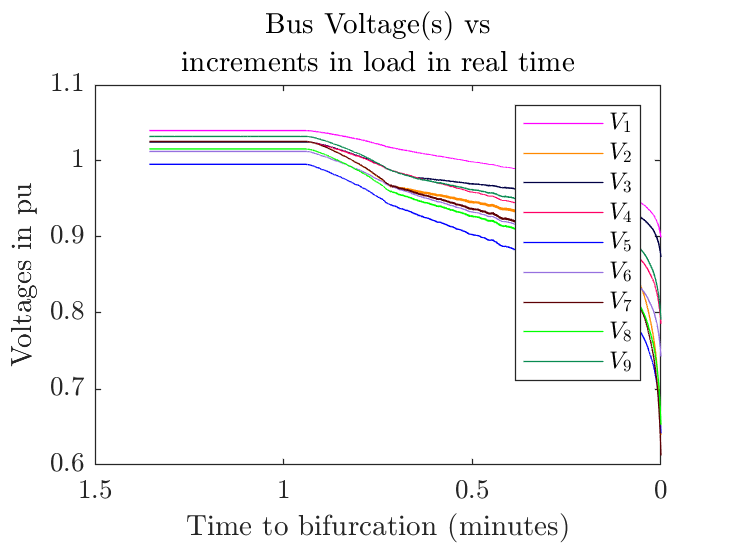

indicesToPlot2 = 1:bifurcationIdx-W;
xaxis2 = (bifurcationIdx - indicesToPlot2)*sampling_rate/(60);

figure('Name', 'Bus Voltages vs Load Increments in Real Time')
plot(xaxis1, volts(indicesToPlot1,1:end));
set(gca,'xdir','reverse')
set(gca,'colororder', rgb)
xlabel('Time to bifurcation (minutes)');
ylabel('Voltages in pu');
title('Bus Voltage(s) vs', ...
    'increments in load in real time');
legend(labelVoltages);

#### Plot Branch MVAs

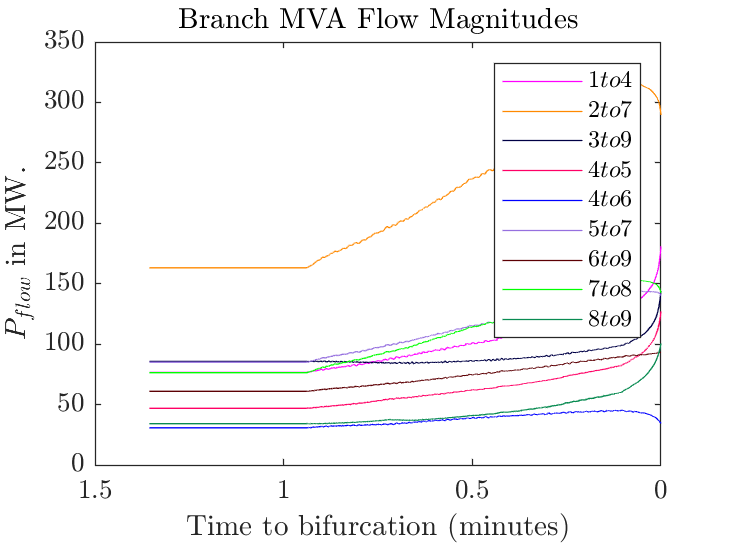

figure('Name', ...
    'Branch MVA flows vs increments in load in real time')
plot(xaxis1, ...
    mvaflowsArr(indicesToPlot1,1:end));
set(gca,'xdir','reverse')
set(gca,'colororder', rgb)
xlabel('Time to bifurcation (minutes)');
ylabel('$P_{flow}$ in MW.');
title('Branch MVA Flow Magnitudes');
legend(labelMVAflows);   

#### Plot Branch Currents.

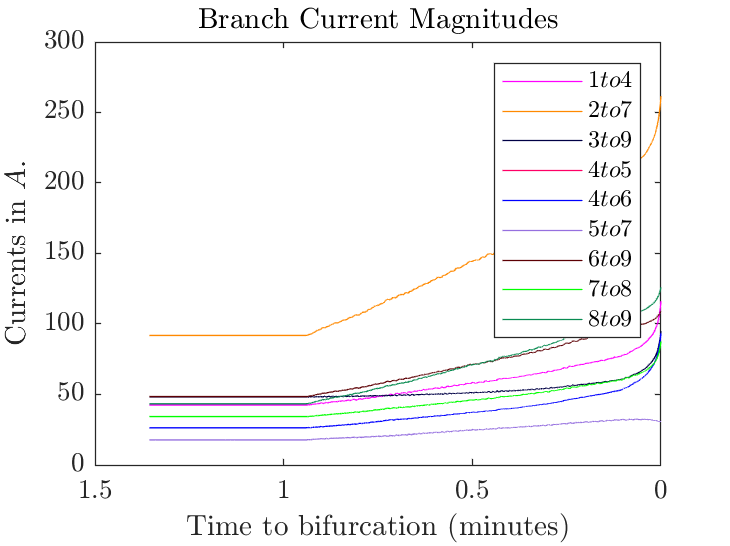

figure('Name', 'Branch Current Flows')
plot(xaxis1, ...
    currentsArr(indicesToPlot1,1:end));
set(gca,'xdir','reverse')
set(gca, 'ColorOrder', rgb)
xlabel('Time to bifurcation (minutes)');
ylabel('Currents in $A$.');
title('Branch Current Magnitudes');
legend(labelcurrents);   


toc

Elapsed time is 5.858869 seconds.
